disp("*** VEHICLE DATA ***");

*** VEHICLE DATA ***


t_0_100_s = interp1(Vv_kph.data,Vv_kph.time,100);
fprintf("Acceleration time = %0.2f s",t_0_100_s)

Acceleration time = 6.11 s


xv_max_km = max(Xv_km.data);
fprintf("Travelled distance = %0.2f km",xv_max_km);

Travelled distance = 11.84 km


av_max_mps2 = max(av_mps2.data);
fprintf("Maximum acceleration = %0.2f m/s^2",av_max_mps2);

Maximum acceleration = 5.00 m/s^2


Vv_max_kph = max(Vv_kph.data);
fprintf("Maximum vehicle speed = %0.2f kph",Vv_max_kph);

Maximum vehicle speed = 227.51 kph


Pw_max_kW = max(Pw_kw.data);
fprintf("Maximum wheel power = %0.2f kW",Pw_max_kW);

Maximum wheel power = 187.16 kW


Fw_max_N = max(Fw_N.data);
fprintf("Maximum wheel traction force = %0.2f N",Fw_max_N);

Maximum wheel traction force = 9784.10 N


Fres_max_N = max(Fres_N.data);
fprintf("Maximum wheel resistive force = %0.2f N",Fres_max_N);

Maximum wheel resistive force = 1426.53 N


Tq_w_max_Nm = max(Tq_w_NM.data);
fprintf("Maximum wheel torque = %0.2f Nm",Tq_w_max_Nm);

Maximum wheel torque = 3206.25 Nm

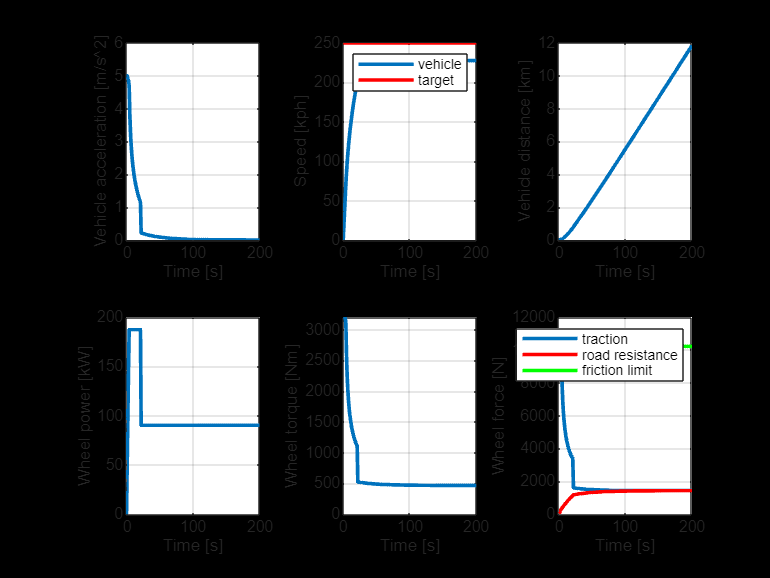


figure(1)
hf1 = gcf;
hf1.Color = [0, 0, 0];
hf1.Name  = "VEHICLE DATA";

% 1.2.1 Vehicle acceleration
subplot(2,3,1)
plot(av_mps2,"LineWidth",2)
ylabel("Vehicle acceleration [m/s^2]")
xlabel("Time [s]")
grid()

% 1.2.2 Vehicle speed
subplot(2,3,2)
plot(Vv_kph,"LineWidth",2)
hold on
plot(Vt_kph,"r","LineWidth",2)
ylabel("Speed [kph]")
xlabel("Time [s]")
legend('vehicle','target')
grid()

% 1.2.3 Vehicle distance
subplot(2,3,3)
plot(Xv_km,"LineWidth",2)
ylabel("Vehicle distance [km]")
xlabel("Time [s]")
grid()

% 1.2.4 Wheel power
subplot(2,3,4)
plot(Pw_kw,"LineWidth",2)
ylabel("Wheel power [kW]")
xlabel("Time [s]")
grid()

% 1.2.5 Wheel torque
subplot(2,3,5)
plot(Tq_w_NM,"LineWidth",2)
ylabel("Wheel torque [Nm]")
xlabel("Time [s]")
grid()

% 1.2.6 Wheel force
subplot(2,3,6)
plot(Fw_N,"LineWidth",2)
hold on
plot(Fres_N,"r","LineWidth",2)
hold on
plot(Fres_N.time,ones(length(Fres_N.time),1)*Ff_max_N,"g","LineWidth",2)
ylabel("Wheel force [N]")
xlabel("Time [s]")
legend("traction", "road resistance", "friction limit") 
grid()


% 2. Electric machine data

% 2.1 Get performance data
disp("*** ELECTRIC MACHINE DATA ***")

*** ELECTRIC MACHINE DATA ***



% 2.1.1 Find maximum electric machine torque
Tq_EM_max_Nm = max(Tq_EM_NM.data);
fprintf("Maximum EM torque = %0.2f Nm",Tq_EM_max_Nm)

Maximum EM torque = 375.00 Nm


% 2.1.2 Find maximum electric machine power
P_EM_max_kW = max(P_EM_KW.data);
fprintf("Maximum EM power = %0.2f kW",P_EM_max_kW)

Maximum EM power = 197.02 kW


% 2.1.3 Find maximum electric machine speed
N_EM_max_rpm = max(N_EM_rpm.data);
fprintf("Maximum EM speed = %0.2f rpm",N_EM_max_rpm)

Maximum EM speed = 16574.30 rpm


% 2.1.4 Find maximum electric machine efficiency
eta_EM_max_pct = max(eta_EM_pct.data);
fprintf("Maximum EM efficiency = %0.2f %",eta_EM_max_pct)

Maximum EM efficiency = 94.54 


% 2.1.5 Find minimum electric machine efficiency
eta_EM_min_pct = min(eta_EM_pct.data);
fprintf("Minimum EM efficiency = %0.2f %",eta_EM_min_pct)

Minimum EM efficiency = 78.00 


% 2.1.6 Find average electric machine efficiency
eta_EM_avg_pct = sum(eta_EM_pct.data)/length(eta_EM_pct.data);
fprintf("Average EM efficiency = %0.2f %",eta_EM_avg_pct)

Average EM efficiency = 80.06 

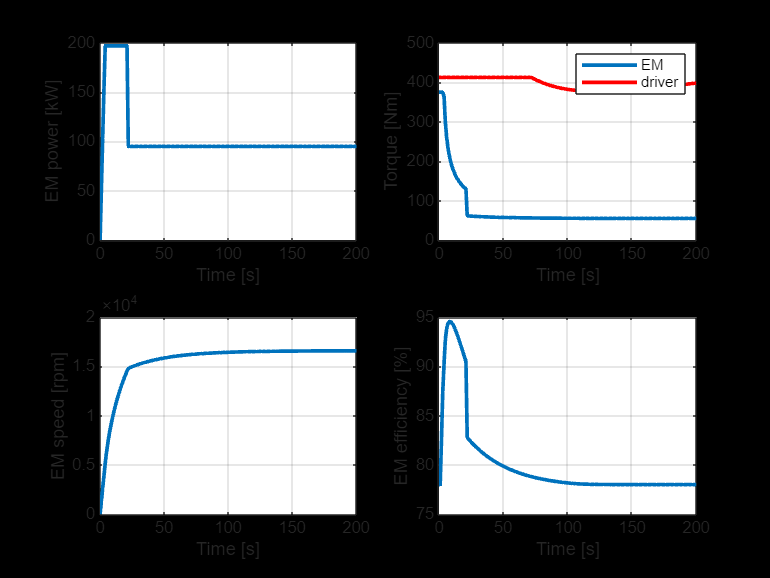


% 2.2 Plot EM data
figure(2);
hf2 = gcf();
hf2.Color = [0, 0, 0];
hf2.Name = "EM DATA";

% 2.2.1 EM power
subplot(2,2,1)
plot(P_EM_KW,"LineWidth",2)
ylabel("EM power [kW]")
xlabel("Time [s]")
grid()

% 2.2.2 EM torque
subplot(2,2,2)
plot(Tq_EM_NM,"LineWidth",2)
hold on
plot(Tq_drv_NM,"r","LineWidth",2)
ylabel("Torque [Nm]")
xlabel("Time [s]")
grid()
legend("EM","driver")

% 2.2.3 EM speed
subplot(2,2,3)
plot(N_EM_rpm,"LineWidth",2)
ylabel("EM speed [rpm]")
xlabel("Time [s]")
grid()

% 2.2.4 EM efficiency
subplot(2,2,4)
plot(eta_EM_pct,"LineWidth",2)
ylabel("EM efficiency [%]")
xlabel("Time [s]")
grid()


% 3. Battery data

% 3.1 Get performance data
disp("*** BATTERY DATA ***")

*** BATTERY DATA ***



% 3.1.1 Find maximum battery current
Ipack_max_A = max(I_pack_A.data);
fprintf("Maximum battery current = %0.2f A",Ipack_max_A)

Maximum battery current = 582.23 A


% 3.1.2 Find maximum battery power
Ppack_max_kW = max(Ppack_KW.data);
fprintf("Maximum battery power = %0.2f kW",Ppack_max_kW)

Maximum battery power = 225.03 kW

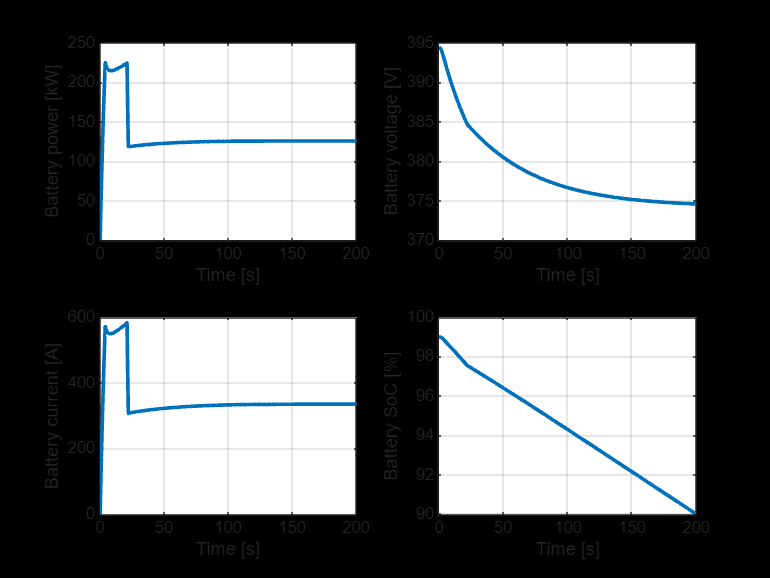


% 3.2 Plot EM data
figure(3);
hf3 = gcf();
hf3.Color = [0, 0, 0];
hf3.Name = "BATTERY DATA";

% 3.2.1 Battery power
subplot(2,2,1)
plot(Ppack_KW,"LineWidth",2)
ylabel("Battery power [kW]")
xlabel("Time [s]")
grid()

% 3.2.2 Battery voltage
subplot(2,2,2)
plot(U_pack_V,"LineWidth",2)
ylabel("Battery voltage [V]")
xlabel("Time [s]")
grid()

% 3.2.3 Battery current
subplot(2,2,3)
plot(I_pack_A,"LineWidth",2)
ylabel("Battery current [A]")
xlabel("Time [s]")
grid()

% 2.2.4 Battery SoC
subplot(2,2,4)
plot(SOC_pack_pct,"LineWidth",2)
ylabel("Battery SoC [%]")
xlabel("Time [s]")
grid()

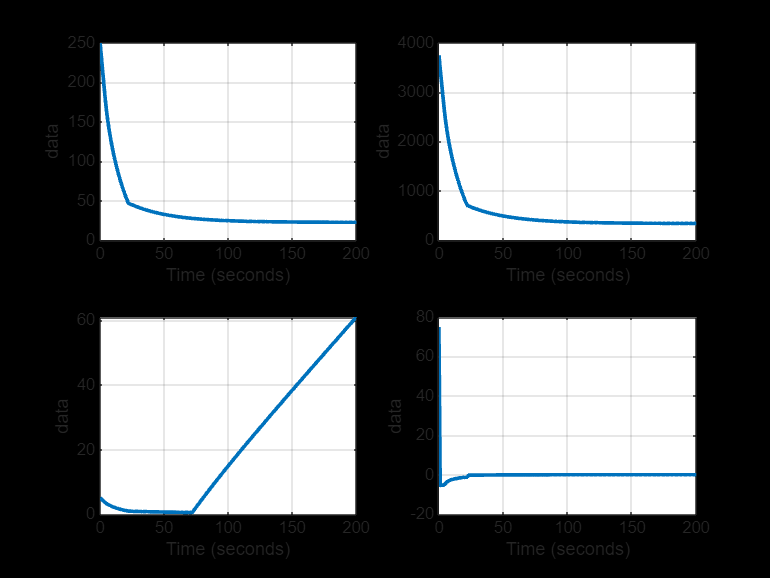


% 4. DEBUG
figure(4);
hf4 = gcf();
hf4.Color = [0, 0, 0];
hf4.Name = "PID DEBUG";
subplot(2,2,1)
plot(Vv_err_kph,"LineWidth",2)
title("Vehicle speed error")
grid()
subplot(2,2,2)
plot(Tq_P_NM,"LineWidth",2)
title("P-torque")
grid()
subplot(2,2,3)
plot(Tq_I_NM,"LineWidth",2)
title("I-torque")
grid()
subplot(2,2,4)
plot(Tq_D_NM,"LineWidth",2)
title("D-torque")
grid();